#  ユニモーダル学習×ベイズ最適化（村田）

# 差圧のときはdropoutを導入すること

 
s = settings;
s.matlab.fonts.editor.title.Style.PersonalValue = {'bold'};
s.matlab.fonts.editor.title.Color.PersonalValue = [0 0 255 1];

# 0. ワークスペースの掃除・開いている図の削除

matlabでは

clcでコマンドラインの履歴の削除

clearでワークスペースの変数の削除

close all hiddenで最小化されているグラフも含めて全て削除

することが出来ます. 

 
clc;
clear;
close all hidden;

# 1. Excelデータの取り込み

RawDataクラスによってExcelデータを取り込みます. 

 
data1 = "20251114"; %trainData
data2 = "20251117"; %testData

%data1 = "20231215";
%data2 = "20231216";

dataCreator = RawDataCreatorWave();

%trainVF for Void Fraction data, trainPr for Pressure difference data

trainVF = dataCreator.createVF(data1,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。



trainPr = dataCreator.createPr(data1,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


testVF = dataCreator.createVF(data2,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


testPr = dataCreator.createPr(data2,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。



%trainVF = dataCreator.createVF(data1,80, Conditions.c28, Labels.c28_normal, true, CorrectConditions.c28_liquidChange);
%trainPr = dataCreator.createPr(data1,80, Conditions.c28, Labels.c28_normal, true, CorrectConditions.c28_liquidChange);
%testVF = dataCreator.createVF(data2,80, Conditions.c28, Labels.c28_normal, true, CorrectConditions.c28_liquidChange);
%testPr = dataCreator.createPr(data2,80, Conditions.c28, Labels.c28_normal, true, CorrectConditions.c28_liquidChange);

rawAllData= RawAllDataBeforeFormatWave([trainVF, trainPr, testVF, testPr]);

%前処理インスタンスの作成. ここでは計測周波数をそろえ, ボイド率の補正を行う. 
preProcessor = PreProcessorBeforeFormatWave({@intervalUniformerWave, @correctWithCapacitanceBaseWave});
%前処理の実行
trainVF = preProcessor.process(trainVF,rawAllData);

trainPr = preProcessor.process(trainPr,rawAllData);
testVF = preProcessor.process(testVF,rawAllData);

testPr = preProcessor.process(testPr,rawAllData);

# 2. データ拡張(スライディングウィンドウ法)

流石に一本の時系列データだけでは不足しているため, 一個ずらしのx点で切り取ってデータを増やします. 流石に一本の時系列データだけでは不足しているため, 一個ずらしのx点

Paragraph で切り取ってデータを増やします. 

 
stride = 1; %各データごとに何計測点飛ばすか. ふつうは1
dataWidth = 400; % データ幅. ここは調整して良い. いつもは300で統一
interval = 0; %データをいくつ飛ばしでdataWIdth点だけ取るか. ふつうは0

%optionの作成 
dataFormatterOption = DataFormatterOptionWave(stride,dataWidth,interval);
%dataFormatter本体を作るクラスにoptionを流し込む (この一段は拡張性のために一応2021年に実装したけど, いらなかったかも)
dataFormatterCreator = DataFormatterCreatorWave(dataFormatterOption);
%optionにしたがってデータをデータ拡張してくれるインスタンスの作成
dataFormatter = dataFormatterCreator.create();

%データ拡張を実施
trainVF = dataFormatter.Format(trainVF);
trainPr = dataFormatter.Format(trainPr);
testVF = dataFormatter.Format(testVF);
testPr = dataFormatter.Format(testPr);

# 3. 訓練及びテストデータ作成(分類)

 ここで、静電容量値か圧力かを選択する。

 
trainTestDataCreator = TrainTestDataCreatorWave();

% VFのみを使用する場合:
%[train, test] = trainTestDataCreator.createAndPreProcessMultimodalWaveData(trainVF, testVF, @cellInputStandardizeOneWave);
% Prのみを使用する場合:
[train, test] = trainTestDataCreator.createAndPreProcessMultimodalWaveData(trainPr, testPr, @cellInputStandardizeOneWave);

# 4. 訓練設定(分類)

訓練を始める前に

- どんな方法で訓練を行うのか, ％

- そもそも深層学習の層をどのように組むのか

を決定します. 

 
initialLearnRate = 0.001;
maxEpoch = 30; % データ全てを何周したら訓練を終わらせるか. 1周は全データが深層学習に一回は入力されたことを意味する(厳密には異なるが)
miniBatchSize = 64;% 一回で深層学習にどれだけのデータを食わせるか. 確率勾配法の肝. まぁとりあえず64でいいかという感じ. 
frequency = 25; % 訓練何回ごとに検証データを入力して上手く学習が進んでいるのかどうかを判断する. 
trainRepeatAmount = 1;% 何回訓練と精度確認を行うか. 精度上昇の効果が見られたとしてもそれがちゃんと再現性のある結果なのかどうかを判断するときに使う.
                                            %x回まわして殆ど全ての場合で精度向上が見られたらokみたいな. 
toleranceTimesForNotImproving = 20; % 訓練中に検証データを入れて, この回数だけ精度の向上が無かった場合には訓練を修了する. 

% どんな設定で訓練を行うのかを保存するインスタンスを作成 
classificationTrainOptionCreator = TrainOptionCreatorWave(train,test);
option = classificationTrainOptionCreator.createNormalTrainOptionWave(initialLearnRate, maxEpoch,miniBatchSize,frequency,trainRepeatAmount,toleranceTimesForNotImproving);

% どんな層の構成(reluとかdropoutとかもここの内部で決める)で訓練を行うのかを保存するインスタンスを作成. 
% カスタム関数を使用する場合は内部の実装の関係上, 出力層(regression層やclassification層)を持つことは許されていないので変更の必要あり.
layerSettingCreator = LayerSettingCreatorOneWave(train,test);

inputsize = 1; %ここが今回は1０
hiddenUnitSize = 320;

% layer = layerSettingCreator.createSingleLSTMLayerForCustomLossFunc(inputsize,hiddenUnitSize);
% 既存のカスタム関数用メソッド名 (LayerSettingCreatorWave のもの) から、
% 新しいクラスのカスタムループ用メソッド名に置き換え
%layer = layerSettingCreator.createLSTMLayerForTrainLoop(inputsize,hiddenUnitSize);
layers = layerSettingCreator.createLSTMLayerForStandardTrain(inputsize,hiddenUnitSize);

# 5. 訓練開始(分類)

 
% ★ ここを修正 ★
% 以前のカスタム層設定変数 'layer' の代わりに、インスタンス 'layerSettingCreator' を渡す
dummyLayers = [];  % 標準学習では未使用

% ★★★ ここを修正: hiddenUnitSize (320) を5番目の引数として追加 ★★★
trainActivator_one = TrainActivatorOneWave( ...
    train, ...              % 1. TrainTestDataWave
    test, ...               % 2. TrainTestDataWave
    option, ...             % 3. TrainOption
    dummyLayers, ...        % 4. netLayers (カスタムループ用。今回は [] or dummyLayers)
    hiddenUnitSize, ...     % ★★★ 5. hiddenUnitSize (必須) ★★★
    layerSettingCreator ... % 6. LayerSettingCreatorOneWave
    );

% データを自動で処理し、trainnetwork を実行する
disp('--- 訓練開始 ---');

--- 訓練開始 ---


データの準備中...
訓練を開始します...


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　４２．１９％　｜　４９．９９％　｜　　　　１．３８５３　｜　１．２９１５　｜　　０．００１０　｜
｜　　　　　　１　｜　　　２５　｜　　　　　００：００：２８　｜　　　　　５４．６９％　｜　５８．０４％　｜　　　　１．０１３０　｜　０．９４０６　｜　　０．００１０　｜
｜　　　　　　１　｜　　　５０　｜　　　　　００：００：４０　｜　　　　　６２．５０％　｜　５８．３３％　｜　　　　０．９３１２　｜　０．９２５２　｜　　０．００１０　｜
｜　　　　　　１　｜　　　７５　｜　　　　　００：００：５３　｜　　　　　６７．１９％　｜　５０．２８％　｜　　　　０．９４４３　｜　０．８６９５　｜　　０．００１０　｜
｜　　　　　　１　｜　　１００　｜　　　　　００：０１：０６　｜　　　　　７５．００％　｜　７３．２７％　｜　　　　０．７９７７　｜　０．７３２９　｜　　０．００１０　｜
｜　　　　　　１　｜　　１２５　｜　　　　　００：０１：１９　｜　　　　　５６．２５％　｜　７３．６３％　｜　　　　０．８２８９　｜　０．７３９４　｜　　０．００１０　｜
｜　　　　　　１　｜　　１５０　｜　　　　　００：０１：３１　｜　　　　　５７．８１％　｜　６３．１９％　｜　　　　０．７９７４　｜　０．７０２９　｜　　０．００１０　｜
｜　　　　　　１　｜　　１７５　｜　　　　　００：０１：４４　｜　　　　　５６．２５％　｜　６４．０１％　｜

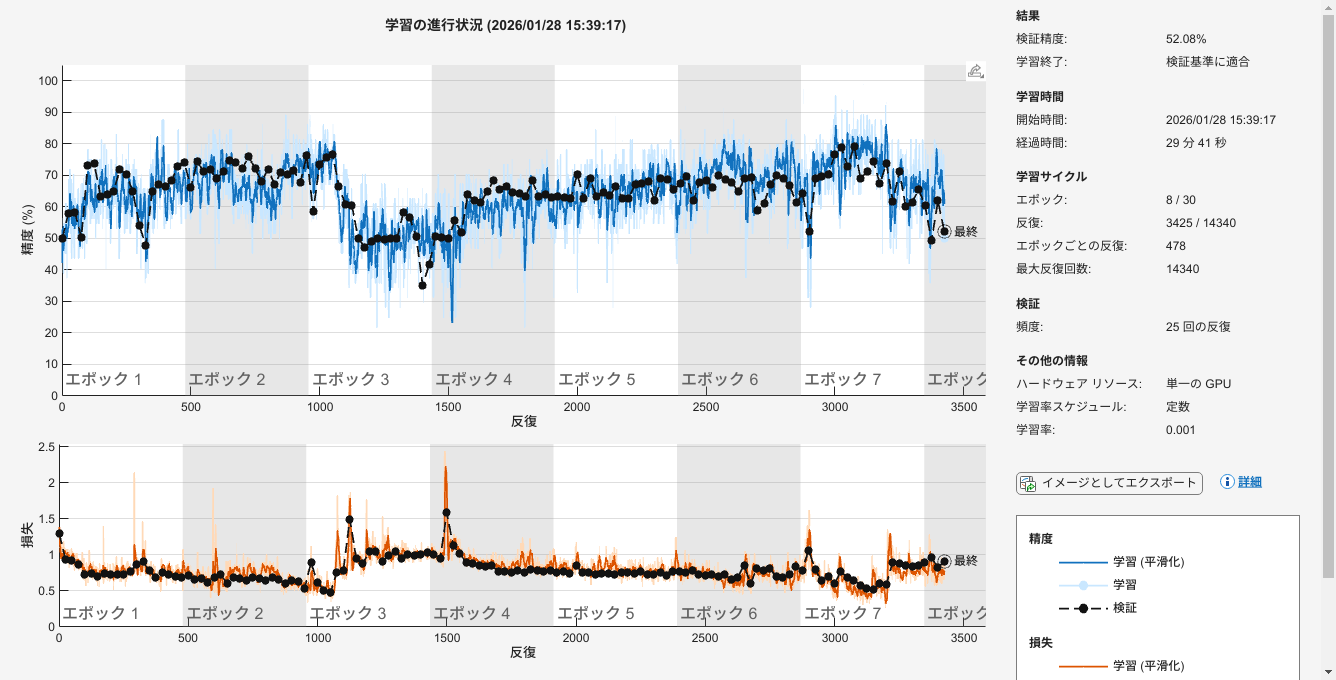

    "✅ 訓練済みネットワークを保存しました: "    "oneWaveNet.mat"



[trainedNet, trainingInfo] = trainActivator_one.trainWithStandardFunction();

disp('--- 訓練完了 ---');

--- 訓練完了 ---



%prefix = "helloWorld/";
%folderName = append(prefix,"test-4/"); % 結果保存ディレクトリ

% 2. customLossFuncActivate メソッドの呼び出し
% 損失関数を、あなたが既に持っている多クロスエントロピー関数に変更
%result = trainActivator_one.customLossFuncActivate("softmax", @multiCrossEntropyLoss, folderName);


%result = trainActivator.activateMultimodal(trainActivator, folderName);　%標準な学習（単一入力）に使用

# 6. 結果の表示(分類)

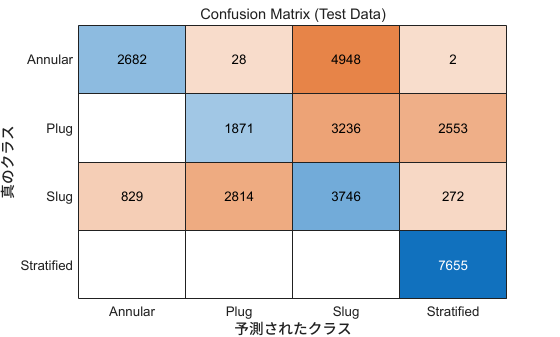

 
XTest = cellfun(@transpose, test.data, 'UniformOutput', false);
YPred = classify(trainedNet, XTest);

figure
confusionchart(test.label, YPred)
title('Confusion Matrix (Test Data)')

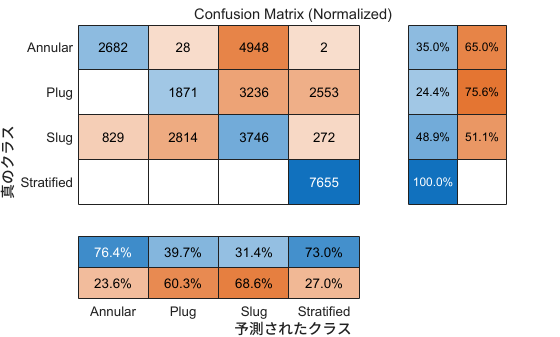


figure
confusionchart(test.label, YPred, ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

title('Confusion Matrix (Normalized)')



%resultDisplyer = ResultDisplayerWave(result,option);
%resultDisplyer.displayResult(folderName);

# 7. それでは損失関数を変えてみましょう. 

ここまでは損失関数はcrossrntropyの通り, シンプルなクロスエントロピー誤差でやっていました. ところで, 深層学習にはoverConfidenceという現象があります. モデルが自信過剰になるものですね. あいまいなところはあいまいで良いのに... 

こういうのに対して損失関数から攻める方法があります. (cf. [https://zenn.dev/bilzard/scraps/d3875d0c5c5e92)](https://zenn.dev/bilzard/scraps/d3875d0c5c5e92))

というわけで, Label Smoothingを使ってみましょう.

なお, 他のloss func: https://knto-h.hatenablog.com/entry/2018/10/09/170000

まずは損失関数の定義からです. 

※定義自体はここではなく, Class->DeepLearning->TrainNet->classification->lossFunc->singleClasssificationに書いてください. (書いた)

次のように損失関数は定義します. 

%{
function func = labelSmoothing(outputLayerName)
arguments
    outputLayerName string
end
%LABELSMOOTHING 正解ラベルの値を1でなく1よりも少しだけ小さな値にすることで、logitが発散するのを抑制する手法。
% cf. https://zenn.dev/bilzard/scraps/d3875d0c5c5e92
% 学習率と連動させてオンライン化するのも面白いかもね. https://qiita.com/T-STAR/items/a3bdcd1ae00150fe1402
function [loss,gradients,state] = labelSmoothingCore(net,trainData,label)
        [predictedLiquid, state] = forward(net,trainData,Outputs=[outputLayerName]);
        %Loss Functionを改造したい時はこの一行を変えてください. ================================
        %predictedLiquid は条件数(12条件とか)*MiniBatchSize(64とか)のdlArrayです. 
        %labelも同じです. どちらもone-hot-表現で出てきます. 
        noise = 0.3; % これ, 色々変えてみてください.  正解クラス以外にどれだけノイズを分配するかです. 
        modifiedTarget = label*(1-noise)+noise/size(label,1);
        lossBeforeMean = -sum((modifiedTarget).*log(predictedLiquid));
        loss = mean(lossBeforeMean); % ミニバッチのため,平均化
        %======================================================================================
        gradients = dlgradient(loss,net.Learnables);

--- ベイズ最適化開始 ---


    end
func = @labelSmoothingCore;
end


それではこの損失関数を使った場合の結果を見てみましょう. 

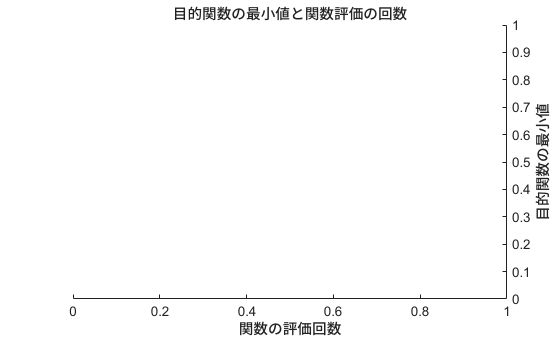

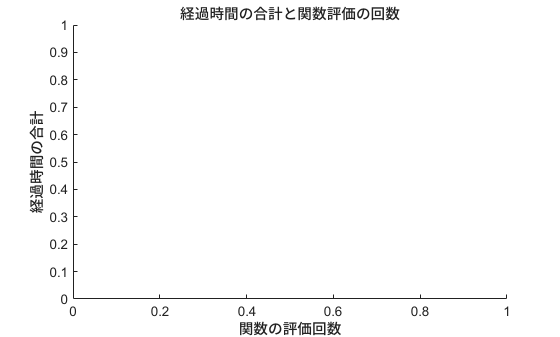

--------------------------------------------------
Trial: LR=0.00025959, Epoch=48, Hidden=484


% 訓練を担当するクラス 
trainActivator = TrainActivator(train,test,option,layer);
prefix = "helloWorld/";
folderName = append(prefix,"test-3-labelSmoothing/");
% 結果が格納されたクラス (カスタム損失関数の時は関数変わります)
result = trainActivator.customLossFuncActivate("softmax",@labelSmoothing,folderName);

# ８．結果の表示

損失関数を変化させた場合の結果の表示をしましょう. 

 
resultDisplyer = ResultDisplayer(result,option);
resultDisplyer.displayResult(folderName);
%}

どうでしょうか, 何か変わりましたかね? 私は確認していないのでここからはあなたが責任を持って結果を解析してみてください. 

# **９．ベイズ最適化**

% 1. TrainTestDataWave インスタンスの作成 (Prデータを使用)
trainTestDataCreator = TrainTestDataCreatorWave();
[train, test] = trainTestDataCreator.createAndPreProcessMultimodalWaveData(trainPr, testPr, @cellInputStandardizeOneWave);

% 2. ★ 必須: .mat ファイルとして保存 ★
% これにより、optimizeModelOneWave 関数内の load() が動作するようになります。
save('train.mat', 'train'); 
save('test.mat', 'test');

% 3. パラメータの定義
vars = [
    optimizableVariable('InitialLearnRate', [1e-4, 1e-2], 'Transform', 'log')
    optimizableVariable('MaxEpoch', [10, 100], 'Type', 'integer')
    optimizableVariable('MiniBatchSize', [32, 128], 'Type', 'integer')
    optimizableVariable('HiddenUnitSize', [128, 512], 'Type', 'integer')
];

% 4. ベイズ最適化の呼び出し
disp('--- ベイズ最適化開始 ---');
results = bayesopt(@optimizeModelOneWave, vars, ...
    'MaxObjectiveEvaluations', 20, ... 
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'Verbose', 1, ...
    'PlotFcn', {@plotMinObjective, @plotElapsedTime}); 

